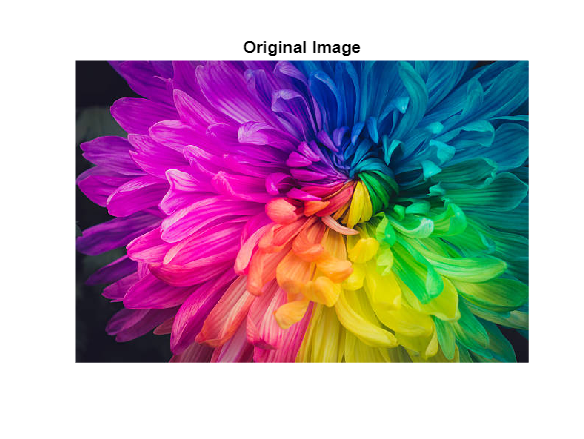

image = imread("image.jpg");
img = rgb2gray(image);

dither1 = averageDithering(img);
dither2 = errorDiffusionDithernig(img, 4);

figure
imshow(image);
title("Original Image");

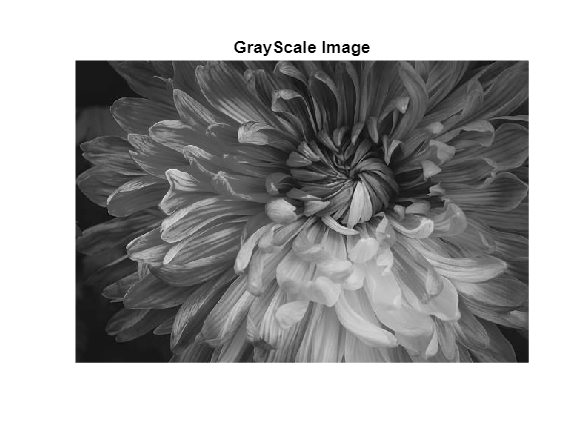


figure  
imshow(img);
title("GrayScale Image");

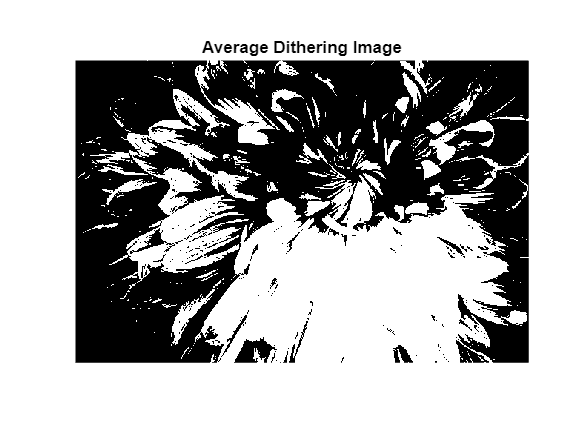


figure
imshow(dither1);
title("Average Dithering Image")

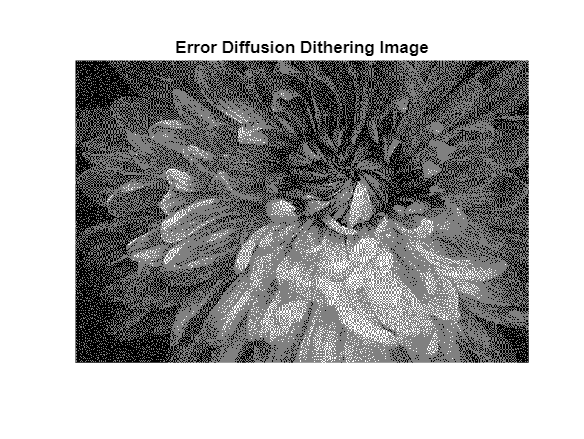

imwrite(dither1, "averageDithering.jpg")

figure
imshow(dither2)
title("Error Diffusion Dithering Image");

imwrite(dither2, "errorDiffusionDithernig.jpg")


function new_img = averageDithering(img)
	[height, width] = size(img);
	avg = 0;
	pixel_num = 0;

	for u = 1:height
		for v = 1:width
			pixel_num = pixel_num + 1;
			avg = avg + 1/pixel_num * (double(img(u, v)) - avg);
		end
	end

	thres = avg * ones(height, width);
	new_img = zeros(height, width);
	for u = 1:height
		for v = 1:width
			if img(u,v) > thres(u,v)
				new_img(u,v) = 255;
			end
		end
	end
end

function new_img = errorDiffusionDithernig(img, b)
    [h, w] = size(img);

    new_img = im2double(img);

    for i = 1: h
        for j = 1: w
            old = new_img(i, j);
            
            new = round(b * old / 2) * (2 / b);

            new_img(i, j) = new;
            err = old - new;
            
            if j < w - 1
                new_img(i, j + 1) = new_img(i, j + 1) + err * 7 / 16;
            end
            
            if i < h - 1
            
                if j > 1
                    new_img(i + 1, j - 1) = new_img(i + 1, j - 1) + err * 3 / 16;
                end

                new_img(i + 1, j) = new_img(i + 1, j) + err * 5/ 16;

                if j < w - 1
                    new_img(i + 1, j + 1) = new_img(i + 1, j + 1) + err * 1 /16;
                end
            end
        end
    end
end